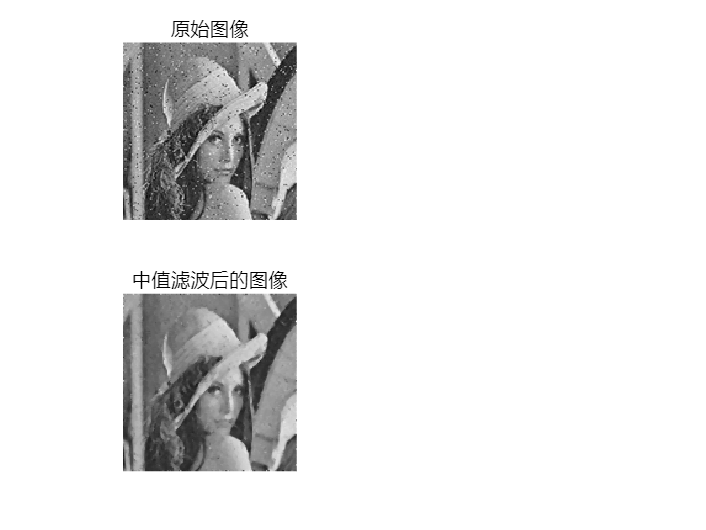

% 中值滤波
clc;close all;clear all;
Image = rgb2gray(imread('待处理图片.png'));
% F = imnoise(I,'gaussian',0, 0.002);
% F = imnoise(I,'salt & pepper',0.06);
[m, n] = size(Image);
G = zeros(m,n);
for x=1:m
    for y = 1:n
        if (x==1||y==1||x==m||y==n)
            G(x,y)=Image(x,y);
        else  % 选出第5大的数
            H = sort([Image(x-1,y-1), Image(x-1,y),Image(x-1,y+1),Image(x,y),... 
                Image(x,y+1),Image(x+1,y-1),Image(x+1,y),Image(x+1,y+1)]);
            G(x,y)=median(H);
        end
    end
end

figure
subplot(221)
imshow(Image);
title('原始图像');
% subplot(222)
% imshow(uint8(F));
% title('加入椒盐噪声后的图像');
subplot(223)
imshow(uint8(G));
title('中值滤波后的图像');

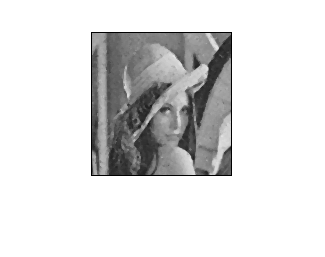

clc;close all;clear all;
Image = rgb2gray(imread('待处理图片.png'));

filter_size = 3;

% 获取输入图像的尺寸
[rows, cols] = size(Image);

% 初始化输出图像
filtered_image = zeros(rows, cols);

% 计算滤波器半径
radius = floor(filter_size / 2);

% 对每个像素进行中值滤波
for i = radius + 1:rows - radius
    for j = radius + 1:cols - radius
        % 提取当前像素周围的邻域
        neighborhood = Image(i - radius:i + radius, j - radius:j + radius);

        % 对邻域进行排序并取中值
        sorted_neighborhood = sort(neighborhood(:));
        median_value = sorted_neighborhood((filter_size * filter_size + 1) / 2);

        % 将中值赋给输出图像的对应像素
        filtered_image(i, j) = median_value;
    end
end

imshow(uint8(filtered_image));